%%FigF: Eigenvalue convergence, Spatial POD
clear all;
load('Y:\rawdata\Sandia_cavity\StructuresToPlot_AIAAJournal\FigF.mat');
eig1 = load(FigF.completeName);
FigF

FigF = struct with fields:
           lname: 'Eigenvalue convergence SPOD'
    completeName: 'Y:\rawdata\Sandia_cavity\ConvergenceResults\Mach0.8\eigval_ensN_5000.txt'
             pts: [1×100 double]
          xtick1: [20 40 60 80 100]
          ytick1: [0 0.2000 0.4000 0.6000 0.8000 1]
         xlabel1: 'l'
         ylabel1: '\eta_c_o_n_v'
            mpts: [1 10 20 30 40 50 60 70 80 90 100]
           ylim1: [0 1]


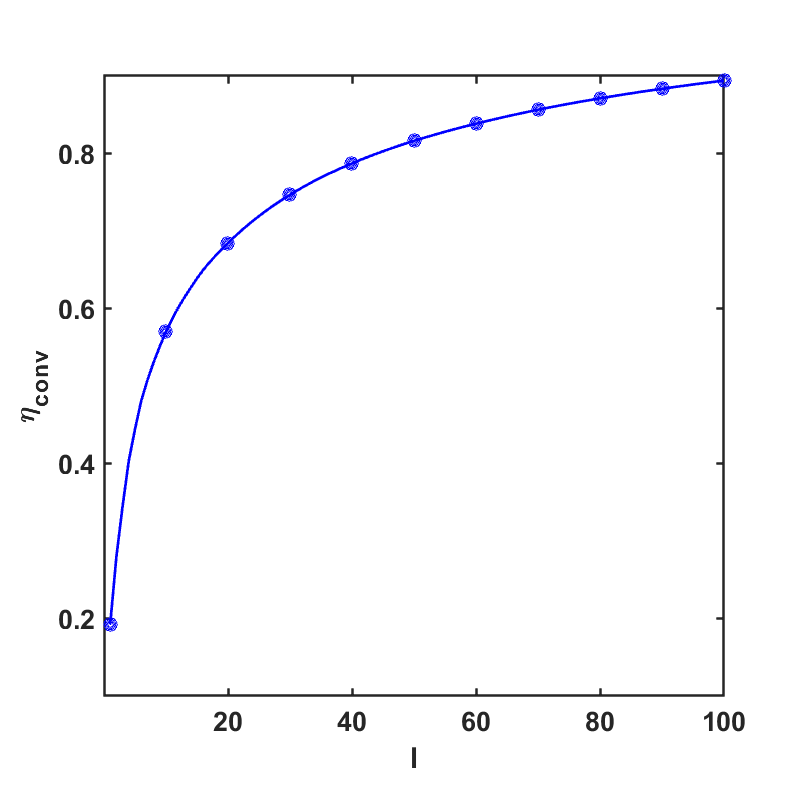

eig2 = en_cnvr_ary(eig1);
plot(FigF.pts,eig2(FigF.pts),'Color',[0 0 1],'LineWidth',2);
hold on;
plot(FigF.mpts,eig2(FigF.mpts),'o','MarkerEdgeColor',[0 0 1],'MarkerSize',8);

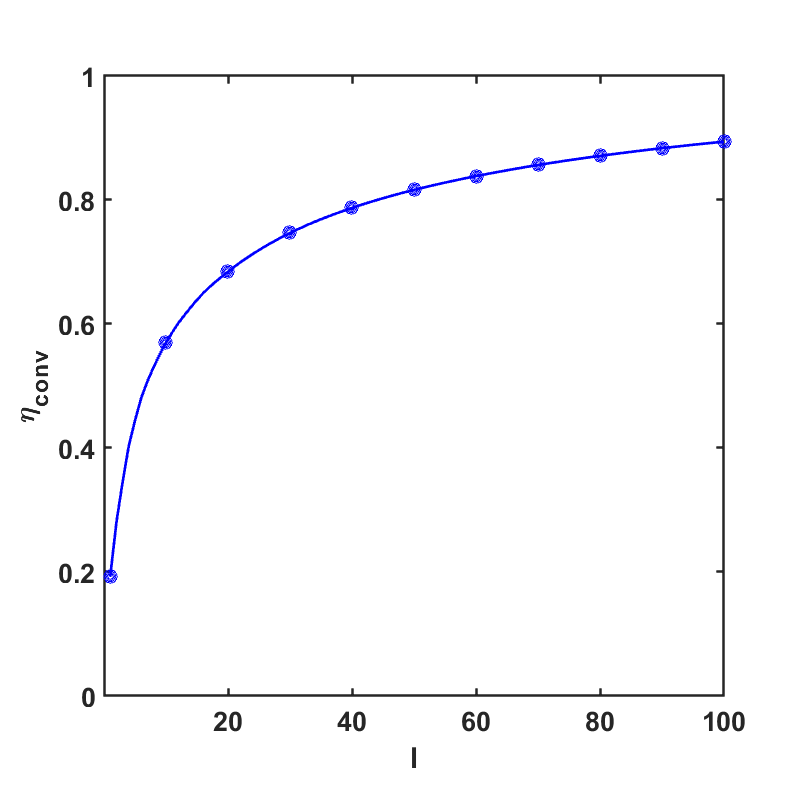

format_graph(1);
xticks(FigF.xtick1);
yticks(FigF.ytick1);
xlabel(FigF.xlabel1);
ylabel(FigF.ylabel1);
ylim(FigF.ylim1);

%%FigG
clear all;
load('Y:\rawdata\Sandia_cavity\StructuresToPlot_AIAAJournal\FigG.mat');
eig1 = load(FigG.completeName);
FigG

FigG = struct with fields:
           lname: 'FPOD lambda vs f'
    completeName: 'Y:\rawdata\Sandia_cavity\SpectralConvergenceResults\eigval_280.txt'
             pts: [2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46]
           xlim1: [0.0441 2]
           ylim1: [0 0.0500]
         xlabel1: 'St_L'
         ylabel1: '\eta_l_,_f'
            xpts: [1×45 double]


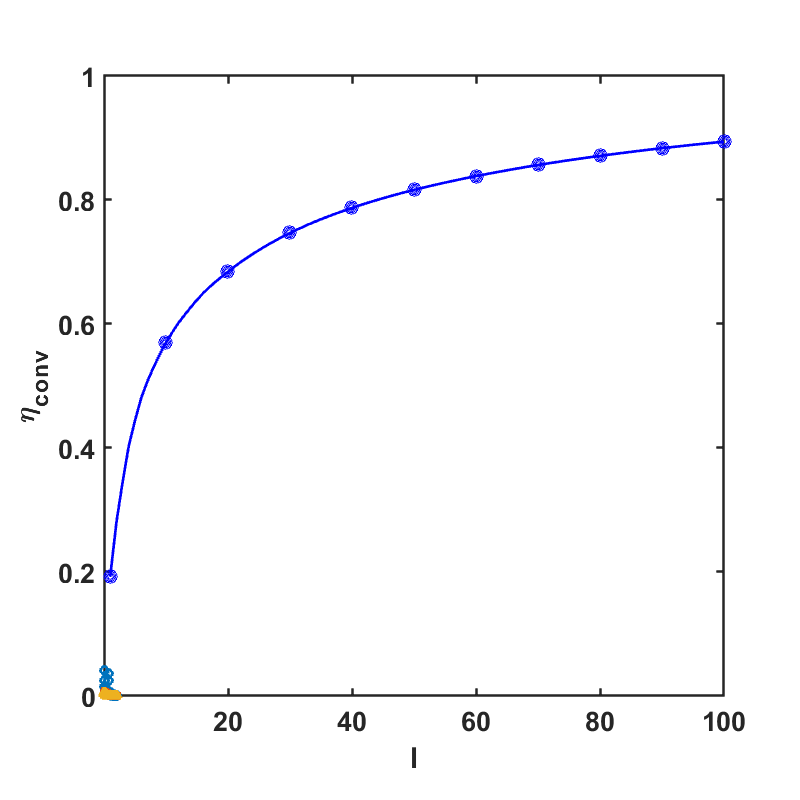

eig2 = eig1/sum(sum(eig1));
plot(FigG.xpts,eig2(1,FigG.pts),'o-',FigG.xpts,eig2(2,FigG.pts),'s-',FigG.xpts,eig2(3,FigG.pts),'^-','LineWidth',2);
format_graph(1);